# Calibration ECM model from P2D model

We calibrate the ECM model parameters from the EIS response of a P2D model. The calibration is done for a set of state of charge.

## P2D reference model

We load the data of the P2D model. The input is the same as for the P2D simulation

We load first the material parameters

filename = fullfile('ParameterData','ParameterSets','Chen2020','chen2020_lithium_ion_battery.json');
jsonstruct_material = parseBattmoJson(filename);

Then, the geometrical parameters

filename = fullfile('Examples', 'JsonDataFiles', 'geometryChen.json');
jsonstruct_geometry = parseBattmoJson(filename);

We merge the two

jsonstruct_p2d = mergeStructs({jsonstruct_material, ...
                               jsonstruct_geometry});

The calibration is done at different state of charge. To dei

soc_values = linspace(0, 1, 5);

The results of the calibration is given in a struct where the fields are functions given in the battmo table format (see below)


  EIS fitting for SOC = 0.00 (1/5)
Linearization...
It:  0 | val: 6.987e+00 | ls-its: NaN | pgrad: 5.308e+03
It:  1 | val: 6.800e+00 | ls-its:   3 | pgrad: 4.615e+03
Line search at max step size, Wolfe conditions not satisfied for this step.
Hessian not updated during iteration 2.
It:  2 | val: 3.511e+00 | ls-its:   3 | pgrad: 2.404e+03
It:  3 | val: 1.981e+00 | ls-its:   2 | pgrad: 3.104e+03
It:  4 | val: 1.850e+00 | ls-its:   2 | pgrad: 5.327e+03
It:  5 | val: 1.657e+00 | ls-its:   2 | pgrad: 4.937e+03
It:  6 | val: 1.472e+00 | ls-its:   2 | pgrad: 1.324e+03
It:  7 | val: 1.134e+00 | ls-its:   1 | pgrad: 6.249e+03
It:  8 | val: 4.576e-01 | ls-its:   1 | pgrad: 1.162e+04
It:  9 | val: 3.201e-01 | ls-its:   1 | pgrad: 4.032e+03
It: 10 | val: 2.851e-01 | ls-its:   3 | pgrad: 3.832e+03
It: 11 | val: 2.749e-01 | ls-its:   1 | pgrad: 2.151e+03
It: 12 | val: 2.655e-01 | ls-its:   1 | pgrad

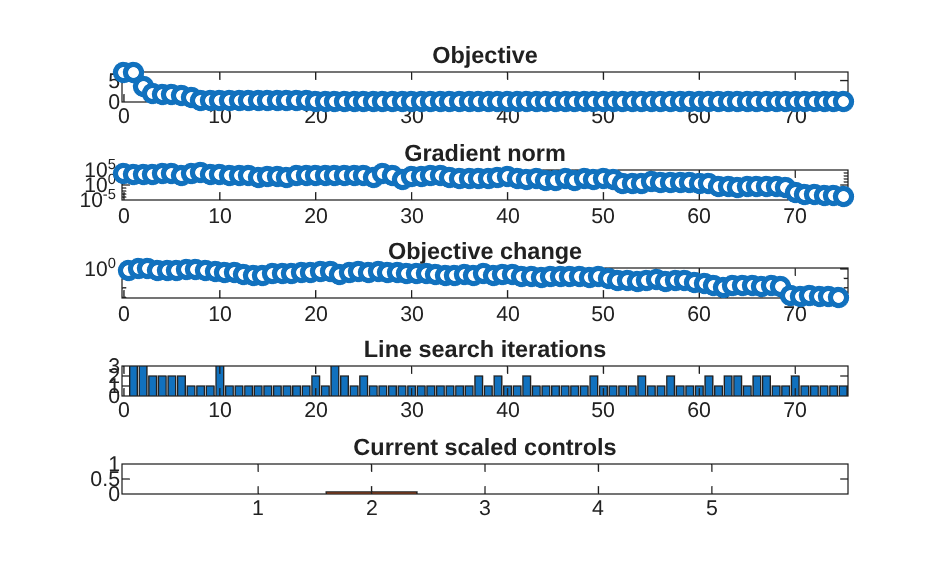

Stopped because reached objChangeTol = 1.000000e-15.

  EIS fitting for SOC = 0.25 (2/5)
Linearization...
It:  0 | val: 8.954e+00 | ls-its: NaN | pgrad: 4.214e+04
It:  1 | val: 2.386e+00 | ls-its:   2 | pgrad: 4.200e+04
It:  2 | val: 6.237e-01 | ls-its:   3 | pgrad: 3.946e+03
It:  3 | val: 5.353e-01 | ls-its:   1 | pgrad: 7.458e+02
It:  4 | val: 3.913e-01 | ls-its:   2 | pgrad: 6.875e+02
It:  5 | val: 3.550e-01 | ls-its:   2 | pgrad: 2.365e+03
It:  6 | val: 3.357e-01 | ls-its:   1 | pgrad: 2.153e+03
It:  7 | val: 3.301e-01 | ls-its:   1 | pgrad: 5.395e+02
It:  8 | val: 3.260e-01 | ls-its:   1 | pgrad: 4.899e+02
It:  9 | val: 3.029e-01 | ls-its:   1 | pgrad: 7.325e+02
It: 10 | val: 2.420e-01 | ls-its:   1 | pgrad: 1.377e+03
It: 11 | val: 2.039e-01 | ls-its:   2 | pgrad: 2.739e+03
It: 12 | val: 1.404e-01 | ls-its:   1 | pgrad: 3.469e+03
It: 13 | val: 1.183e-01 | ls-its:   2 | pgrad: 1.94

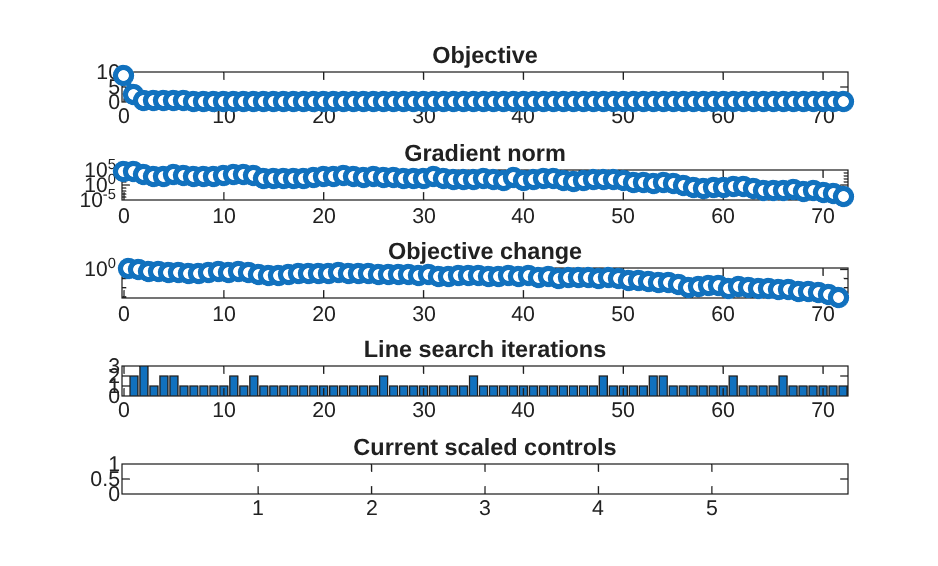

Stopped because reached objChangeTol = 1.000000e-15.

  EIS fitting for SOC = 0.50 (3/5)
Linearization...
It:  0 | val: 1.150e+01 | ls-its: NaN | pgrad: 5.878e+04
It:  1 | val: 1.073e+00 | ls-its:   2 | pgrad: 5.866e+04
It:  2 | val: 8.239e-01 | ls-its:   1 | pgrad: 9.193e+03
It:  3 | val: 7.788e-01 | ls-its:   1 | pgrad: 2.364e+03
It:  4 | val: 4.909e-01 | ls-its:   1 | pgrad: 2.317e+03
It:  5 | val: 3.994e-01 | ls-its:   1 | pgrad: 5.931e+03
It:  6 | val: 3.483e-01 | ls-its:   1 | pgrad: 2.371e+03
It:  7 | val: 3.427e-01 | ls-its:   1 | pgrad: 8.959e+02
It:  8 | val: 3.204e-01 | ls-its:   1 | pgrad: 7.436e+02
It:  9 | val: 3.155e-01 | ls-its:   1 | pgrad: 2.069e+02
It: 10 | val: 3.120e-01 | ls-its:   1 | pgrad: 3.157e+02
It: 11 | val: 3.010e-01 | ls-its:   1 | pgrad: 4.231e+02
It: 12 | val: 2.770e-01 | ls-its:   1 | pgrad: 4.085e+02
It: 13 | val: 1.273e-01 | ls-its:   3 | pgrad: 1.99

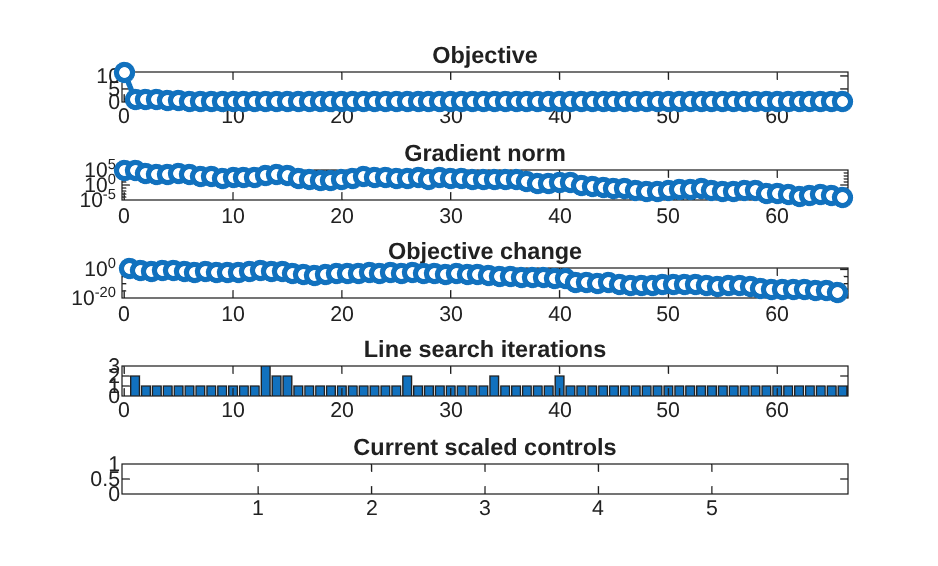

Stopped because reached objChangeTol = 1.000000e-15.

  EIS fitting for SOC = 0.75 (4/5)
Linearization...
It:  0 | val: 8.482e+00 | ls-its: NaN | pgrad: 4.450e+04
It:  1 | val: 1.638e+00 | ls-its:   2 | pgrad: 4.438e+04
It:  2 | val: 1.310e+00 | ls-its:   1 | pgrad: 9.690e+03
It:  3 | val: 1.187e+00 | ls-its:   1 | pgrad: 3.459e+03
It:  4 | val: 5.903e-01 | ls-its:   2 | pgrad: 3.475e+03
It:  5 | val: 5.155e-01 | ls-its:   2 | pgrad: 5.984e+03
It:  6 | val: 3.935e-01 | ls-its:   1 | pgrad: 5.144e+03
It:  7 | val: 3.896e-01 | ls-its:   1 | pgrad: 4.230e+02
It:  8 | val: 3.778e-01 | ls-its:   1 | pgrad: 6.503e+02
It:  9 | val: 3.614e-01 | ls-its:   1 | pgrad: 1.200e+03
It: 10 | val: 3.410e-01 | ls-its:   1 | pgrad: 1.064e+03
It: 11 | val: 3.136e-01 | ls-its:   1 | pgrad: 2.141e+02
It: 12 | val: 2.846e-01 | ls-its:   1 | pgrad: 1.665e+03
It: 13 | val: 2.069e-01 | ls-its:   1 | pgrad: 2.63

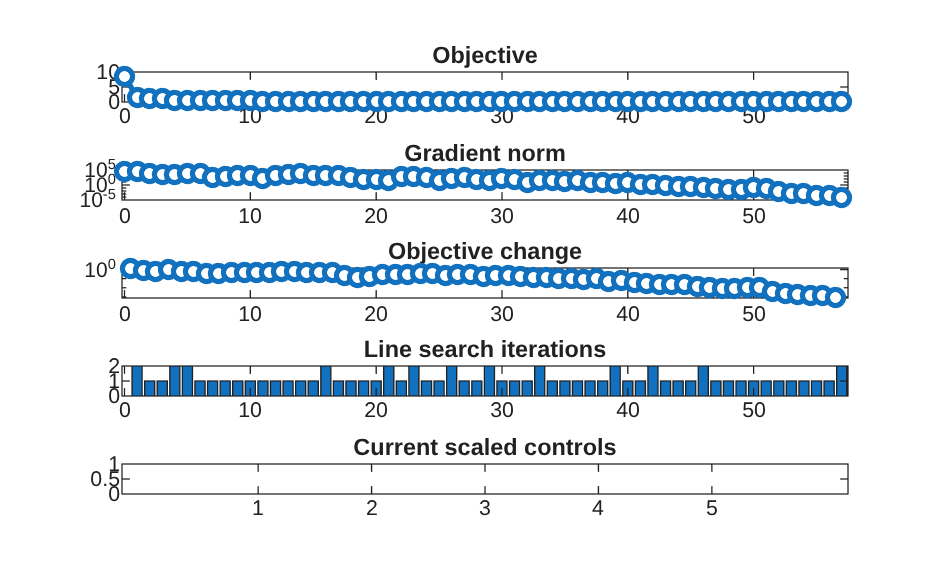

Stopped because reached objChangeTol = 1.000000e-15.

  EIS fitting for SOC = 1.00 (5/5)
Linearization...
It:  0 | val: 2.621e+00 | ls-its: NaN | pgrad: 8.263e+03
It:  1 | val: 2.017e+00 | ls-its:   3 | pgrad: 7.736e+03
It:  2 | val: 1.700e+00 | ls-its:   1 | pgrad: 6.742e+03
It:  3 | val: 5.475e-01 | ls-its:   2 | pgrad: 3.835e+03
It:  4 | val: 5.228e-01 | ls-its:   2 | pgrad: 2.868e+03
It:  5 | val: 4.326e-01 | ls-its:   1 | pgrad: 2.808e+03
It:  6 | val: 4.081e-01 | ls-its:   1 | pgrad: 9.097e+02
It:  7 | val: 3.719e-01 | ls-its:   1 | pgrad: 8.472e+02
It:  8 | val: 2.844e-01 | ls-its:   1 | pgrad: 1.840e+03
It:  9 | val: 2.010e-01 | ls-its:   1 | pgrad: 3.173e+03
It: 10 | val: 1.568e-01 | ls-its:   1 | pgrad: 2.809e+03
It: 11 | val: 1.483e-01 | ls-its:   1 | pgrad: 9.534e+02
It: 12 | val: 1.470e-01 | ls-its:   1 | pgrad: 2.361e+02
It: 13 | val: 1.357e-01 | ls-its:   1 | pgrad: 2.78

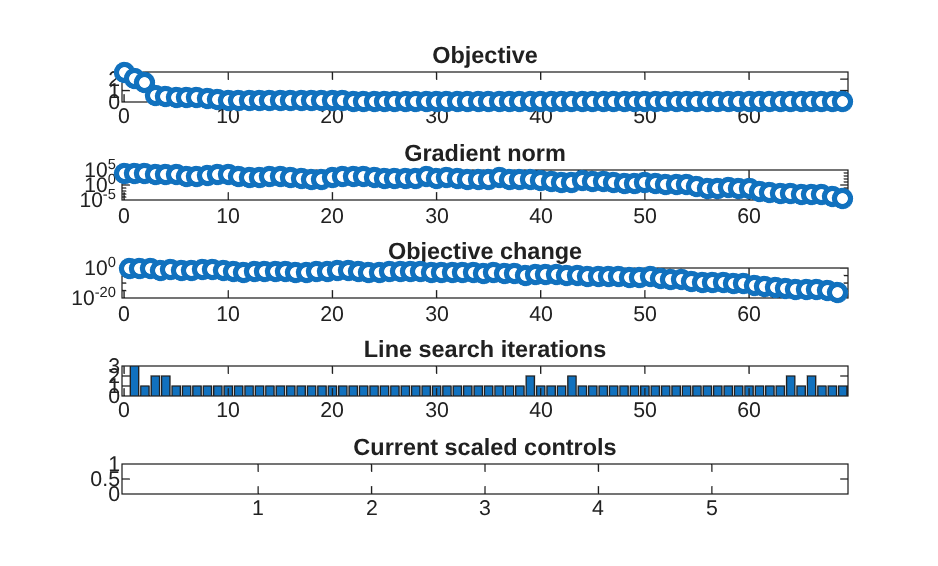

It: 69 | val: 4.284e-02 | ls-its:   1 | pgrad: 4.363e-05
Stopped because reached objChangeTol = 1.000000e-15.
    SOC        R0         R1        C1         R2         C2  
    ____    ________    ______    ______    ________    ______

       0    0.052519    76.352    8866.9    0.018174    2079.9
    0.25    0.035298    16.864     22967    0.014803    3136.9
     0.5    0.032967     8.729     37441     0.01416    3591.5
    0.75    0.034937    10.646     29455    0.016338    3350.5
       1    0.045339    13.785     24495    0.018915    3215.2



jsonstruct = calibrateEcmFromP2D(jsonstruct_p2d, soc_values);

plot the results

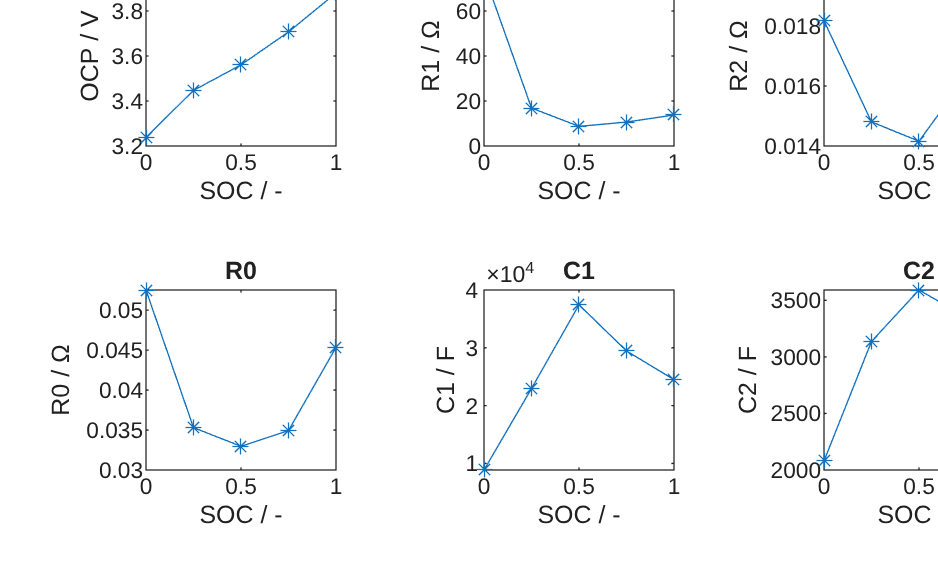

soc = sort(soc_values);

figure
tiledlayout(2, 3, 'tileindexing', 'columnmajor');

nexttile

% the function |setupFunction| creates a function handle from the battmo function input format.
fn = setupFunction(jsonstruct.OCP);
plot(soc, fn(soc), '*-')
title('OCP')
xlabel('SOC / -')
ylabel('OCP / V');

nexttile
fn = setupFunction(jsonstruct.R0);
plot(soc, fn(soc), '*-')
title('R0')
xlabel('SOC / -')
ylabel('R0 / \Omega');

nexttile
fn = setupFunction(jsonstruct.R1);
plot(soc, fn(soc), '*-')
title('R1')
xlabel('SOC / -')
ylabel('R1 / \Omega');

nexttile
fn = setupFunction(jsonstruct.C1);
plot(soc, fn(soc), '*-')
title('C1')
xlabel('SOC / -')
ylabel('C1 / F');

nexttile
fn = setupFunction(jsonstruct.R2);
plot(soc, fn(soc), '*-')
title('R2')
xlabel('SOC / -')
ylabel('R2 / \Omega');

nexttile
fn = setupFunction(jsonstruct.C2);
plot(soc, fn(soc), '*-')
title('C2')
xlabel('SOC / -')
ylabel('C2 / F');